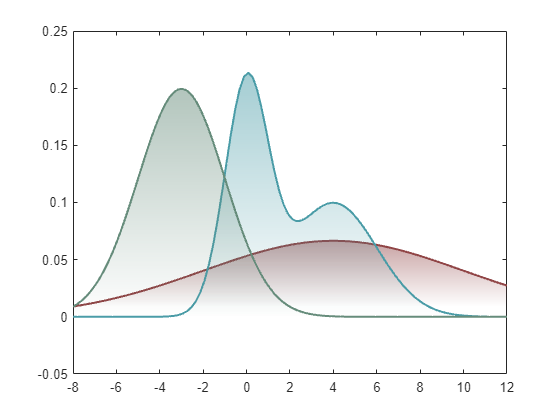

% areahDemo
% 生成数据
x=linspace(-8,12,100);
y1=normpdf(x,4,6);
y2=normpdf(x,0,1).*0.5+normpdf(x,4,2).*0.5;
y3=normpdf(x,-3,2);

% 绘制渐变面积图
hold on
areah(gca,x,y1,'Color',[144,69,70]./255,'LineWidth',1.5);
areah(x,y2,'Color',[74,156,167]./255,'LineWidth',1.5);
areah(x,y3,'Color',[102,140,123]./255,'LineWidth',1.5);

% 简单修饰坐标区域
ax=gca;
ax.XLim=[-8,12];
ax.Box='on';

function areah(varargin)
% @author : slandarer
if isa(varargin{1},'matlab.graphics.axis.Axes')
    ax=varargin{1};varargin(1)=[];
else
    ax=gca;
end
hold on
X=varargin{1};Y=varargin{2};
XList=linspace(min(X(:)),max(X(:)),1000);
YList=linspace(min(Y(:)),max(Y(:)),1000);
[~,YMesh]=meshgrid(XList,YList);
YY=interp1(X(:),Y(:),XList);

coe.Color=lines(ax.ColorOrderIndex);
coe.LineWidth=2;
for i=3:2:length(varargin)
    coe.(varargin{i})=varargin{i+1};
end
CMesh=zeros(1000,1000,3);
CMesh(:,:,1)=ones(1000,1000).*coe.Color(1);
CMesh(:,:,2)=ones(1000,1000).*coe.Color(2);
CMesh(:,:,3)=ones(1000,1000).*coe.Color(3);
AMesh=linspace(0,.5,1000)'.*ones(1,1000);
AMesh(YMesh>YY)=0;

image(ax,[min(X(:)),max(X(:))],[min(Y(:)),max(Y(:))],CMesh,'AlphaData',AMesh)
plot(ax,X(:),Y(:),'Color',coe.Color,'LineWidth',coe.LineWidth)
ax.ColorOrderIndex=ax.ColorOrderIndex+1;
end